# Sampling Operation and Properties of Sampled Signals

In an computer controlled system, since the control algorithm which utilizes measured output signal (feedback signal) is implemented in a processor that operates discrete-time domain (with a triggering clock), the continous-time output signals needed to be sampled, quantized and coverted to the numbers with specific precisions. 

$\bullet$ Compare and see relation of continuous-time signal and discrete signal obtained through sampling over frequency spectrum analysis.

$\bullet$ Perform numerical experiments on selection of sampling period and its effect on output signals for different inputs via frequency spectrum analysis and the time-domain response investigations, and further investigate the related concepts via directed Apps.

$\bullet$ Become familiar with aliasing issue in sampling through frequency spectrum analysis and see the conditions on ideal reconstruction of sampled signals.

This livescript introduces some of the core concepts alongside examples of MATLAB coding to  illustrate the core concepts. 

Related files include: ***Continuous_and_Discrete_time_Mapping_control101.mlapp,  Closed_Loop_Under_Sampling_control101.mlapp, Sampled_Data_Systems_control101.mlx, Signal_Types_in_Computer_Controlled_Systems_control101. ***

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%  
%        help control101         (opens within the command window)

Source files created by Mehmet Kilic, Yaprak Yalcin, Istanbul Technical University (İTÜ) and also available separately from [https://drive.mathworks.com/sharing/bf093c57-7f71-4380-bec3-c0fa6ffdb8b9](https://drive.mathworks.com/sharing/bf093c57-7f71-4380-bec3-c0fa6ffdb8b9) 

Files edited for inclusion in the toolbox by J.A.Rossiter, University of Sheffield    

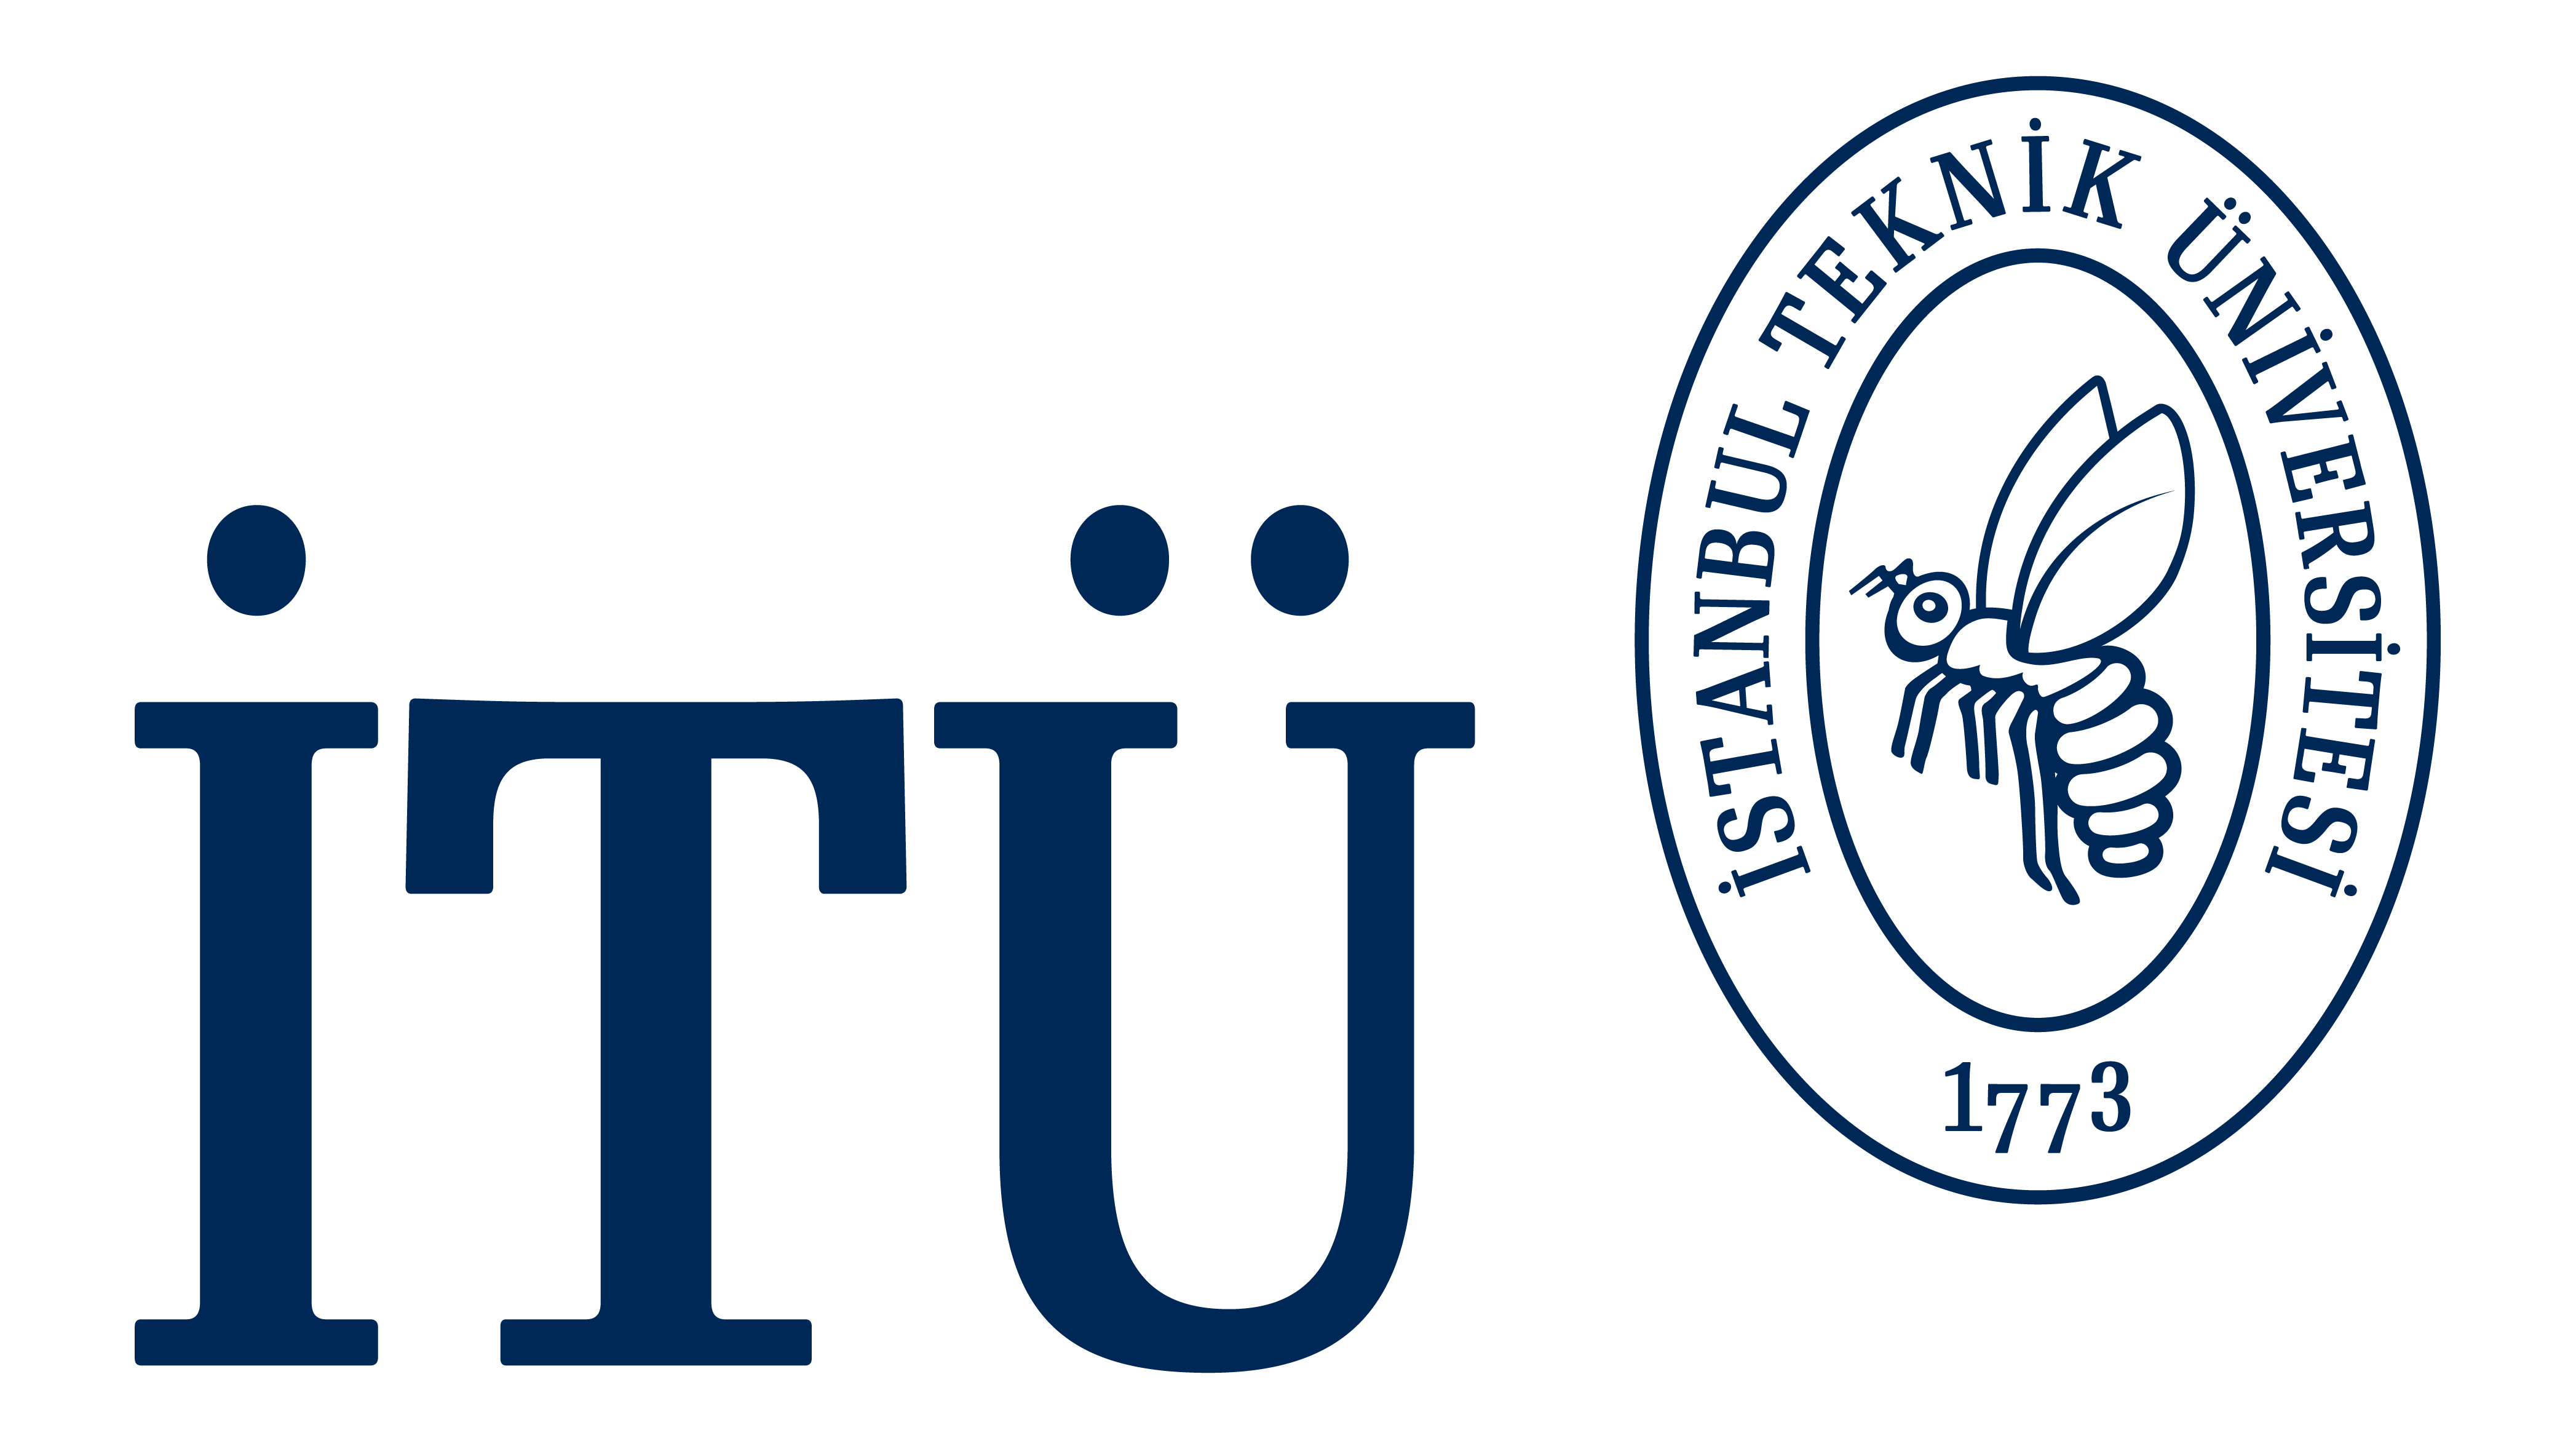                

## Table of contents

- Introduction to sampling oeprations

- Shanon sampling theorem

- The sampling operation

- Analysis of the sampling operation

- The ADC virtual laboratory

## 1 Introduction to sampling operations

In an computer controlled system, since the control algorithm which utilizes measured output signal (feedback signal) is implemented in a processor that operates discrete-time domain (with a triggering clock), the continous-time output signals needed to be sampled, quantized and coverted to the numbers with specific precisions. A sampling operation means measuring (and recording the signal) at some specific time instances. Mostly,  periodic sampling is used. The time between two sampling instants is the called  sampling period (T). The relation between sampling period and sampling frequency is $\omega_{s\;} =2\frac{\pi }{T}$. Multirate sampling may be considered for large plants for which it may be necessary to have control loops with different sampling periods. Usually, the sampler is integrated into AD converters. AD converters also quantize the signal value at the sampling instance to a finite precision number.  AD converters may have 8-16 bit of resolutions for quantization which coresponds to $2^8 -2^{16}$ levels of quantization. Figure 1 illustrates the loss of information with sampling, that is, in essence on the values at the precise sampling points are retained.

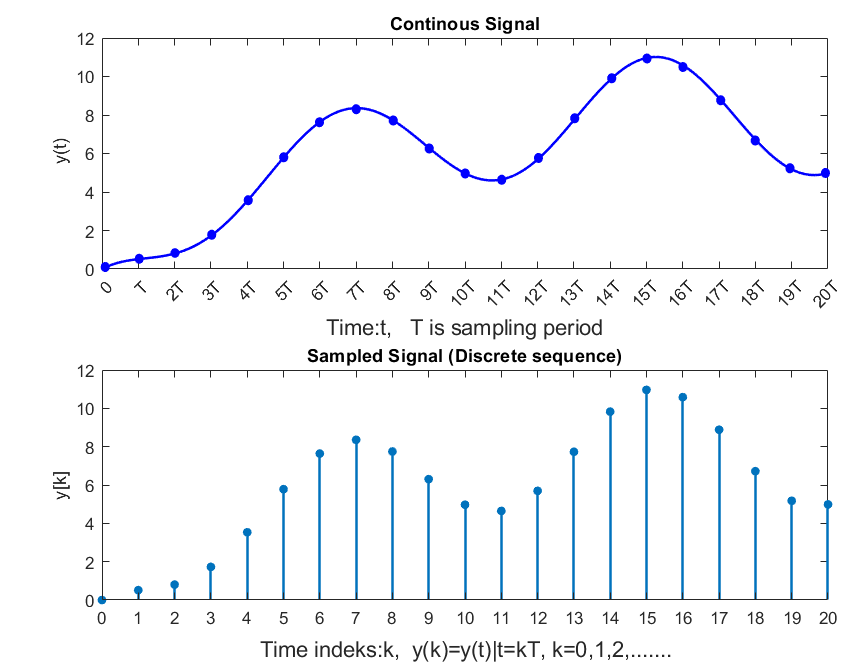

Figure 1 Continous and Sampled Signals

It is clear that the sampling too slowly may cause lose of characteristic and important information of the signal and the system that produce it, in essence any intersample information. If the controller utilises a signal which lacks sufficient information, the closed loop system behavior may be deteriorated and even become unstable.Therefore, the sampling period should be selected carefully. At this point, Shanon Sampling Theorem should be considered.  

Readers can investigate the effect of sampling period selection on open loop and closed-loop behavior of banchmarks systems via the virtual laboratories ***Continuous_and_Discrete_time_Mapping_control101.mlapp ***and*** Closed_Loop_Under_Sampling_control101.mlapp. ***Open using the call statements below directly in the command window***.***

%run Continuous_and_Discrete_time_Mapping_control101
%run Closed_Loop_Under_Sampling_control101

## 2 Shanon Sampling Theorem

The theorem was presented by Claude E. Shannon in 1949 proving that a continous-time signal that doesn't contain higher frequencies than $\omega_{c\;}$ can be uniquely reconstructed from its sampled sequence if the sampling frequency is higher than 2$\omega_{c\;}$. 

More clearly, $\omega_{c\;}$ is the maximum frequency of the sinusoidal signal that contributes the constitution of the band-limited continous signals which is seen in the frequency specturum of the signal shown in Figure 2 and obtained via the continous-time Fourier Transform of the signal.

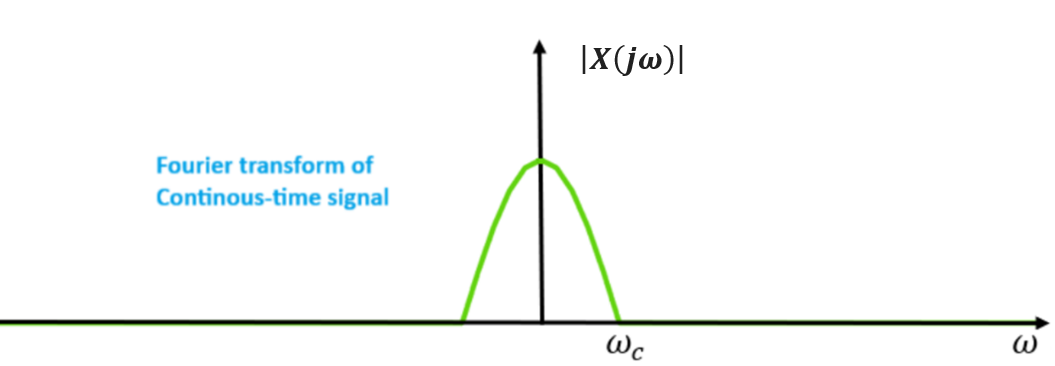

Figure 2 Frequency Spectrum of Band-limited Continous Signals

### 2.1 MATLAB code illustrating Shanon's theorem

The following code considers a continous-time first order system with the transfer function *G = 9 / (s + 10)*. It applies a step signal with magnitute *u=2* and plots the frequency spectrum of the output signal and then further applies this to* u = 2sin(10t)* and plots the frequency spectrum of the output signal.

To aid transparency of the links to the mathematics, symbolic variables are used.

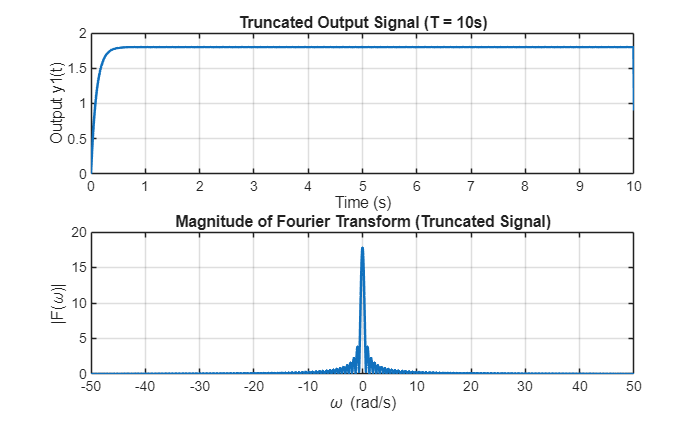

syms s t w T

% Define Transfer function G1(s)
G = 9 / (s + 10);

% Define a step input in Laplace domain (u(t)=2)
u1 = 2;
U1_s = u1 / s;

% Define the step response output Y(s) = G1(s) * U(s)
Y1_s = G * U1_s;

% Compute time-domain output y(t)
y1_t = ilaplace(Y1_s, s, t);

% Truncate the output using a rectangular window: y1_trunc(t) = y1(t) for t in [0, T]
T_val = 10;  % You can change this duration
rect_window = heaviside(t) - heaviside(t - T_val);
y1_trunc = simplify(y1_t * rect_window);

% Compute the continuous Fourier Transform of the truncated signal
F1_w = simplify(fourier(y1_trunc, t, w));

% Define the frequency range
w1_vals = linspace(-50, 50, 2000);
F1_w_func = matlabFunction(F1_w, 'Vars', w);
F1_w_vals = F1_w_func(w1_vals);

% Plot the output signal (truncated)
figure (1);
t_val = 0:0.01:10;
y1_val = double(subs(y1_trunc, t, t_val));

subplot(2, 1, 1);
plot(t_val, y1_val, 'LineWidth', 1.5);
title(['Truncated Output Signal (T = ', num2str(T_val), 's)']);
xlabel('Time (s)');
ylabel('Output y1(t)');
grid on;

% Plot the frequency spectrum
subplot(2, 1, 2);
plot(w1_vals, abs(F1_w_vals), 'LineWidth', 1.5);
xlabel('\omega (rad/s)');
ylabel('|F(\omega)|');
title('Magnitude of Fourier Transform (Truncated Signal)');
grid on;

### 2.2 Example 2 - sinusoidal input

A second example is given here but now based on a sinusodial input.

disp('**********************')

**********************


disp('Section 2.2 below')

Section 2.2 below


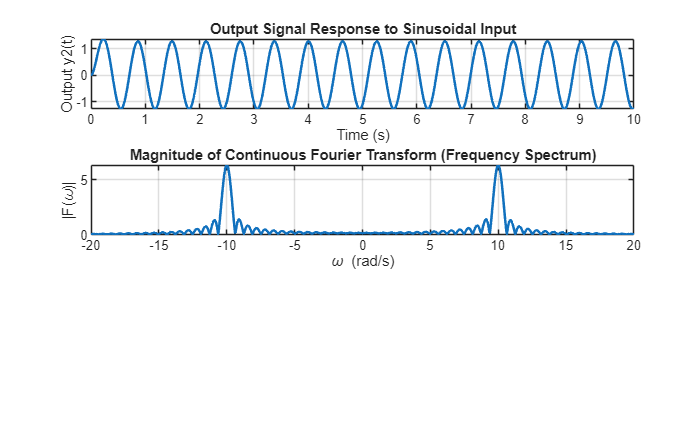

% Laplace transform of sinusoidal input (2sin(5t))
U2_s = 20/(s^2+100);
% Output Y2(s) = G1(s) * U2(s)
Y2_s = G * U2_s;

% Compute time-domain output y(t)
y2_t = ilaplace(Y2_s, s, t);

% Truncate the output using a rectangular window: y2_trunc(t) = y2(t) for t in [0, T]
T_val = 10;  % You can change this duration
rect_window = heaviside(t) - heaviside(t - T_val);
y2_trunc = simplify(y2_t * rect_window);

% Compute the continuous Fourier Transform of the truncated signal
F2_w = simplify(fourier(y2_trunc, t, w));

% Define frequency range
w2_vals = linspace(-20, 20, 1000);  % Define a frequency vector
L2=size(w2_vals);
F2_w_vals =subs(F2_w, w, w2_vals);  % Evaluate Fourier Transform numerically

% Plot the results
figure (2);
t_val = 0:0.01:10; 
y2=double(subs(y2_t, t, t_val));
% Plot the output signal
subplot(3, 1, 1);
plot(t_val, y2, 'LineWidth', 1.5);
title('Output Signal Response to Sinusoidal Input');
xlabel('Time (s)');
ylabel('Output y2(t)');
grid on;

% Plot the frequency spectrum (Magnitude fourier Transform)
subplot(3, 1, 2);
plot(w2_vals, abs(F2_w_vals), 'LineWidth', 1.5);
% xlim([0 1.5]);
xlabel('\omega (rad/s)');
ylabel('|F(\omega)|');
title('Magnitude of Continuous Fourier Transform (Frequency Spectrum)');
grid on;

### 2.3 Exercise for the reader

 Update the code above for these two scenarios. 

-  Change the input magnitute for step input *u=5* and plot the output spectrum.

-  Plot the output spectrum for the input *u=2+2sin(3t)+2cos(5t)*. 

Compare the results with the earlier examples.

## 3 The sampling operation

Mathematically, in the continuous time domain, the sampling operation is represented by the modulation of the signal (multiplication in time domain) with an impulse train signal (periodic series of shifted delta dirac functions) as show in Figure 3. After the modulation the obtained signal $x^* \left(t\right)$ is still in the continous time domain but only takes values of the orginal signal $x\left(t\right)$ at the sampling instances. 

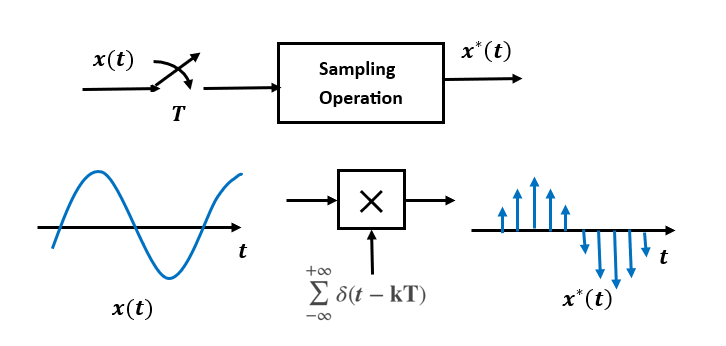

Figure 3. Sampling Operation

The mathematical expression of the impulse train is:

#### $p\left(t\right)=\sum_{-\infty }^{+\infty } \delta \left(\mathit{\mathbf{t}}-\textrm{kT}\right)$.

### 3.1 MATLAB code for demonstrating an impulse train 

The following code generates and plots an impulse train function with  T=1s.

disp('**********************')

**********************


disp('Section 3.1 below')

Section 3.1 below


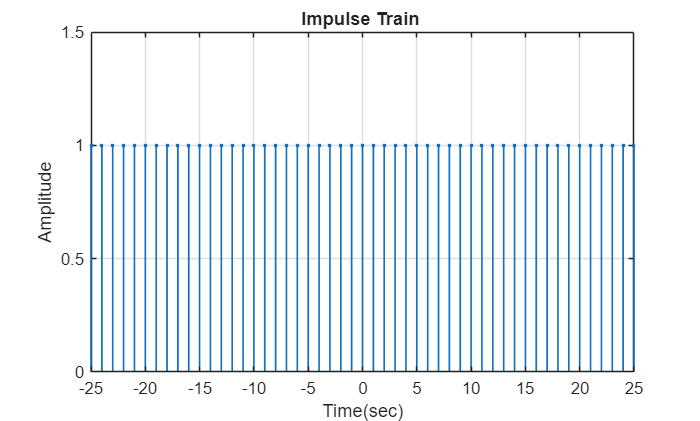


% sampling interval or period
t=-25:1:25;% Time range for impulse train
% creating impulse function
x=@(t) (t==0);
%% impulse train 

sum=zeros(size(t));
for k = -25:25
    sum = sum+x(t-k);
end
figure
stem(t,sum,'.','linewidth',1);grid on;xlabel('Time(sec)');
ylabel('Amplitude');
title('Impulse Train ');
xlim([-25 25]);
ylim([0 1.5]);

**Exercise for the reader: **Change the above code to create an impulse train for sampling periods T=0.5 and T=5.

### 3.2 The sampled signal

The multiplication of the orginal signal with an impulse train gives:

#### 
$$x^* \left(t\right)=x_p \left(t\right)=x\left(t\right)p\left(t\right)$$


This yields the following expression for the sampled signal in the continous time domain.

#### 
$$x^* \left(t\right)=\sum_{-\infty }^{+\infty } x\left(\textrm{kT}\right)\delta \left(t-\textrm{kT}\right)$$


The Figure 4 shows how the orginal signal modulates the impulse train (delta dirac series).       

 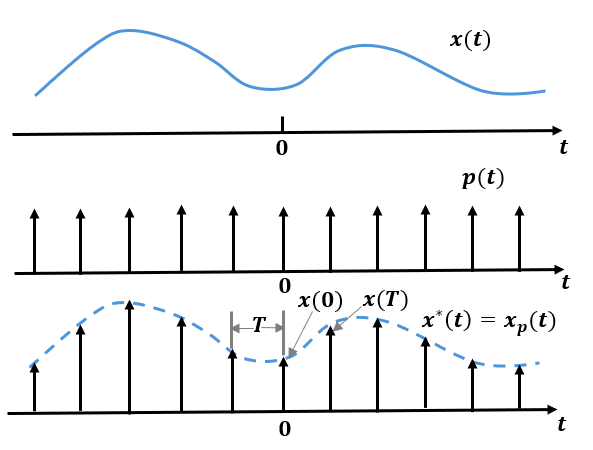

Figure 4. Sampling with an impulse train

Following example code, applies input *u = 2 + sin(5 t-5pi/4)*  to the system G, samples the corresponding output for T=0.1, T=0.5, T=1 and plots the orginal output and sampled output signals. The user can change the definition of the system parameters using the sliders.

disp('**********************')

**********************


disp('Section 3.2 below')

Section 3.2 below



% Define the transfer function
G1 = tf(7, [1, 2])


G1 =
 
    7
  -----
  s + 2
 
Continuous-time transfer function.


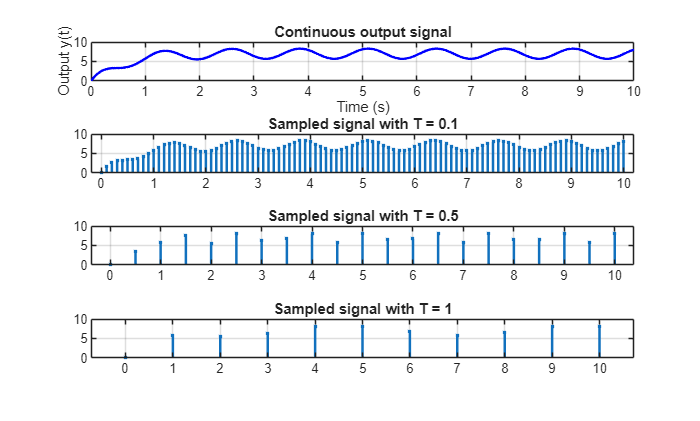


% Define time vector for simulation. High resolution mimics a continous
% time signal
t = 0:1e-4:10;  % Time from 0 to 10 seconds

% Input signal:u = 2 + sin(5* t-5*pi/4);
u = 2 + sin(5*t-5*pi/4);

% Simulate the output response to the input signal
y = lsim(G1, u, t);  % 'lsim' simulates the response to arbitrary input

% Define sampling periods
T_values = [0.1, 0.5, 1];  % Sampling periods

% Initialize figure
figure;

% Plot the output signal
subplot(4, 1, 1);
plot(t, y, 'b', 'LineWidth', 1.5);
title('Continuous output signal');
xlabel('Time (s)');
ylabel('Output y(t)');
grid on;

% Sample and plot the output signal for different T values
for k=1:length(T_values);
    T = T_values(k);

    % Sample the output signal
    sampled_times1 = 0:T:max(t);
    sampled_output1 = y(round(sampled_times1 / (t(2) - t(1))) + 1); % Indexing
    subplot(4, 1, k+1);
    % Plot sampled signals
        stem(sampled_times1, transpose(sampled_output1), '.', 'LineWidth', 1.5);
        title(['Sampled signal with T = ',num2str(T_values(k))])
        grid on
end

## 4 Analysis of the sampling operation

Doing the exercises above, the reader will have noticed that the frequency spectrum of sampled system is periodic. Lets see this result with following mathematical analaysis. 

Applying Laplace transform to the  sampled signal yields:

#### 
$$X^* \left(s\right)=\sum_{k=0}^{+\infty } x\left(\textrm{kT}\right)e^{-\textrm{kTs}}$$


First apply a perodic shift in frequency domain where m is any integer number and $\omega_s =2\pi /T$.

#### 
$$X^* \left(s+{\textrm{jm}\omega }_s \right)=\sum_{k=0}^{+\infty } x\left(\textrm{kT}\right)e^{-k\left(s+{\textrm{jm}\omega }_s \right)T}$$


Next separate the exponential term **into its different components.**

#### 
$$X^* \left(s+{\textrm{jm}\omega }_s \right)=\sum_{k=0}^{+\infty } x\left(\textrm{kT}\right)e^{-\textrm{kTs}} e^{-\textrm{jkm2}\pi }$$


Since $\omega_s =2\pi /T$  and $\left|e^{-\textrm{jkm2}\pi } \right|=1$, this expression is equal to unshifted Laplace transform of the sampled signal.

#### 
$$X^* \left(s+{\textrm{jm}\omega }_s \right)=\sum_{k=0}^{+\infty } x\left(\textrm{kT}\right)e^{-\textrm{kTs}} =X^* \left(s\right)$$


In summary, the bove analysis shows that:

#### 
$$\left|X^* \left(s+{\textrm{jm}\omega }_s \right)\right|=\left|X^* \left(s\right)\right|$$


and

#### 
$$\left|X^* \left(j\omega +{\textrm{jm}\omega }_s \right)\right|=\left|X^* \left(j\omega \right)\right|$$
 

which means the frequency spectrum of the sampled signal is periodic as illustrated in Figure 4 for an indicative *X(s)*.

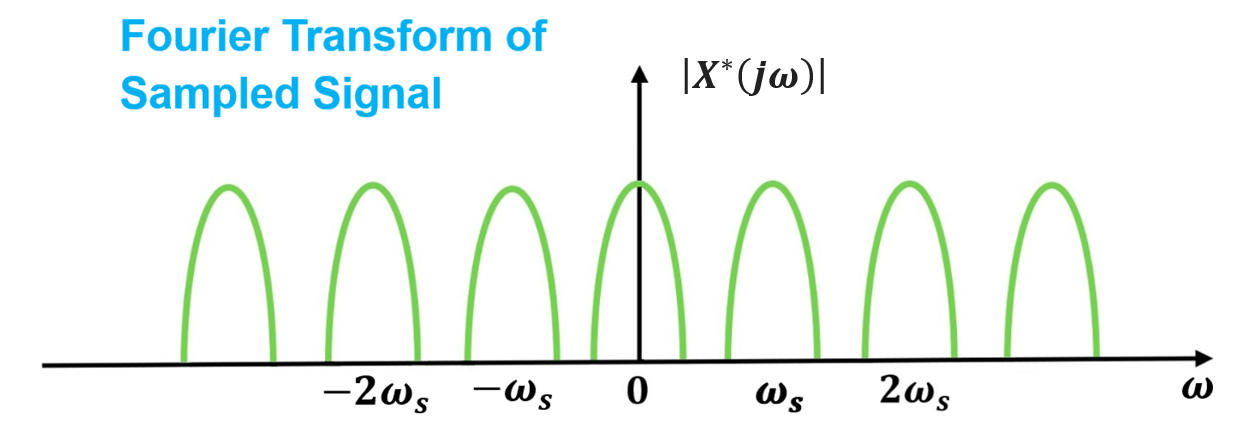

Figure 5. Frequency spectrum of sampled signal

**Exercise**: Consider a system G1, write some code that applies the input signals *u=2, u=2sint *and* u=2sin(5t)* and sample the corresponding outputs with T=0.1, T=0.5, T=1.

### 4.1. Avoiding aliasing

Assume that the Shanon (Nyquist) frequency is $\omega_s =2\omega_c$. In theory it is possible to reconstruct the signal since there isn't intereference among the copies of the spectrum of the orginal signal as seen the figure below**.  In general we required that: **$\omega_s >2\omega_c$.

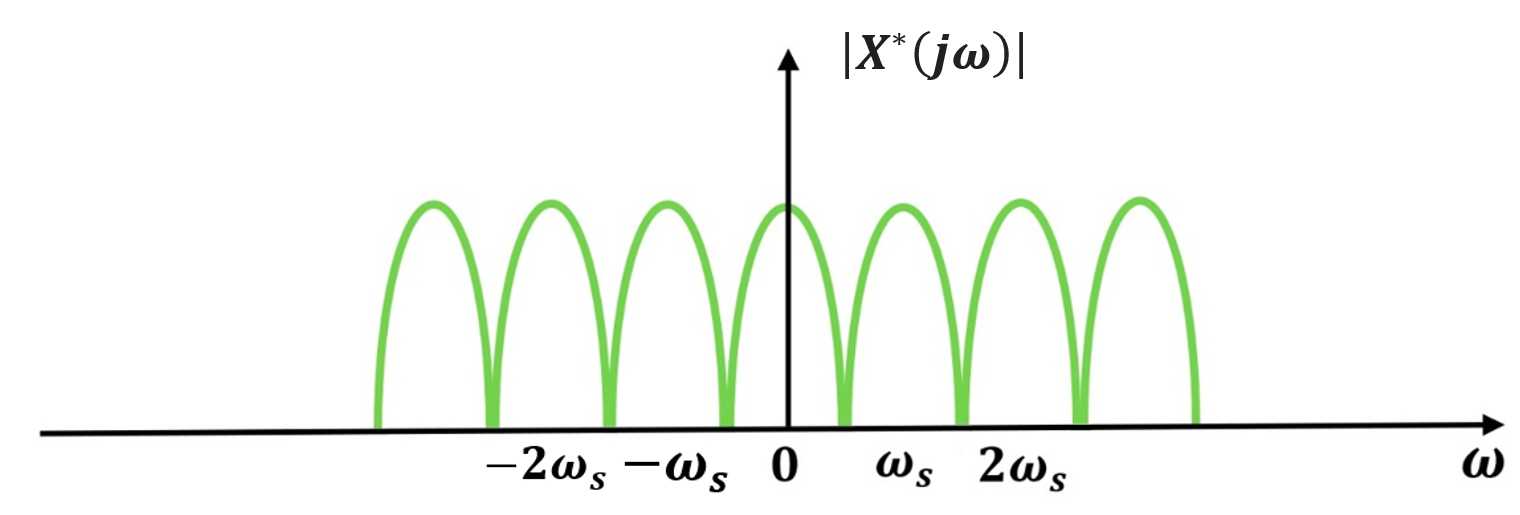

Figure 6 Frequency spectrum of sampled signal for sampling at Shanon frequency

### 4.2 MATLAB code to illustrate the frequency response of a sampled signal  

Define a system G1 (you can use the sliders below to change some of the parameters or indeed replace entirely by entering suitable code) and apply a step signal with magnitude u=2, sample the output signal with the sampling period T=0.1 and plot the spectrum of the sampled signal.

disp('**********************')
disp('Section 4.2 below')

clear;
clc;
% Define the transfer function
G1 = tf(9, [1, 2]);

% Time vector for 100 seconds, high resolution

**********************


t = 0:1e-4:100;    

Section 2.2 below


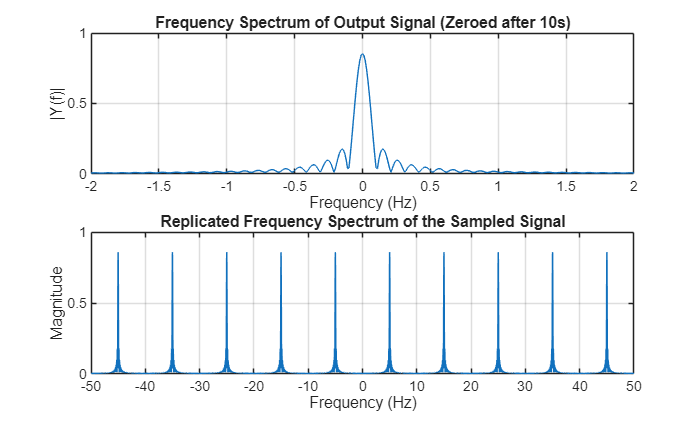

u = 2;

% Step response
[y, t] = step(u * G1, t);

% ----------- Truncation by Zeroing after 10 Seconds -----------
y_truncated = y;
y_truncated(t > 10) = 0;   % Zero out after 10 seconds

% ----------- Fourier Transform of Zeroed Signal -----------
L = length(y_truncated);
Y = fft(y_truncated);
f = (-L/2+0.5:L/2-0.5)*(1/(t(2)-t(1)))/L;
Y_shifted = fftshift(Y);

% ----------- Sampling the Zeroed Signal -----------
T = 0.1;  % Sampling period in seconds
Fs = 1 / T;

sampled_times = 0:T:max(t);
sampled_indices = round(sampled_times / (t(2) - t(1))) + 1;
sampled_output = y_truncated(sampled_indices);

% ----------- Fourier Transform of Sampled Output -----------
L_sampled = length(sampled_output);
Y_sampled = fft(sampled_output);
f_sampled = (-L_sampled/2+0.5:L_sampled/2-0.5)*(Fs/L_sampled);
Y_sampled_shifted = fftshift(Y_sampled);

% ----------- Plotting -----------
figure;

% Plot 1: Spectrum of Zero-Padded Output Signal
subplot(2, 1, 1);
plot(f, abs(Y_shifted)/L);
xlim([-2 2]);
title('Frequency Spectrum of Output Signal (Zeroed after 10s)');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
grid on;

% Plot 2: Replicated Spectrum of Sampled Signal
num_copies = 5;
f_extended = linspace(-num_copies*Fs, num_copies*Fs, num_copies*2*L_sampled);
Y_extended = repmat(abs(Y_sampled_shifted)/L_sampled, num_copies * 2, 1);

subplot(2, 1, 2);
plot(f_extended, abs(Y_extended));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Replicated Frequency Spectrum of the Sampled Signal');
xlim([-num_copies*Fs, num_copies*Fs]);
grid on;

### 4.3 Signal reconstruction

In theory it is possible to reconstruct the orginal signal with a band-limited ideal filter for $\omega_s \ge 2\omega_c$. Figure 7 shows band-limited filter spectrum together with spectrum of the sampled signal. As it is easy to see from the figure multiplications of spectrums in frequency domain yields the spectrum of the orginal signal. 

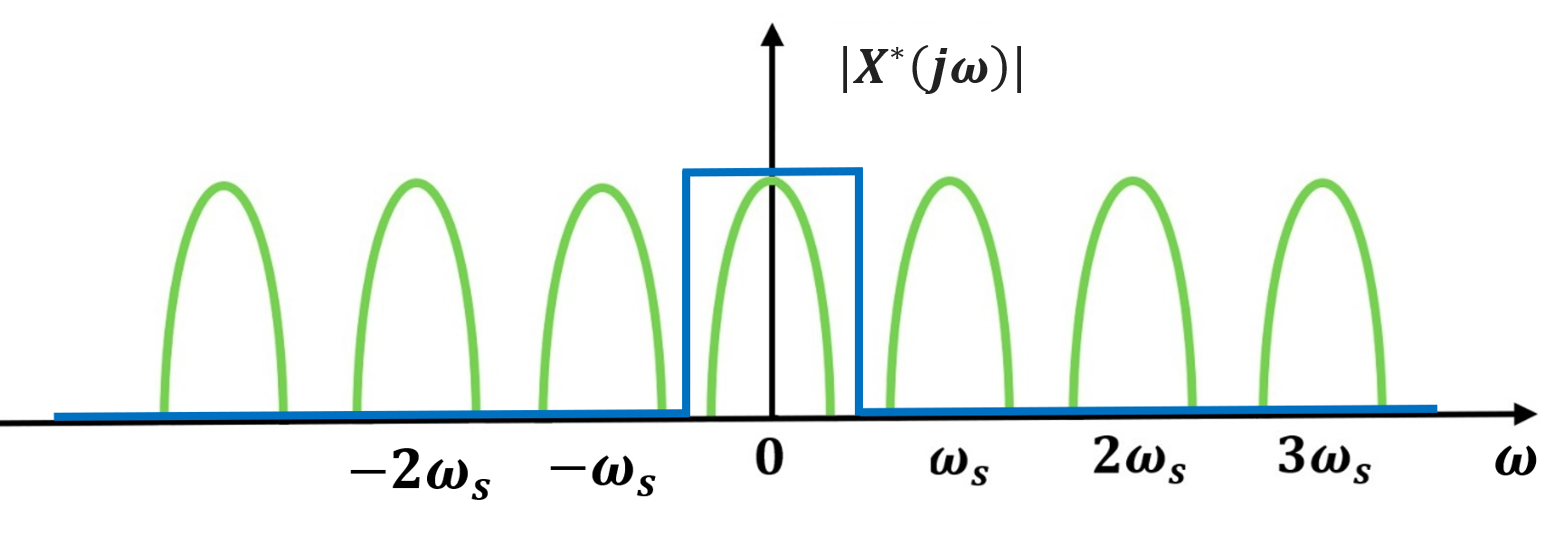

 Figure 7. Frequency spectrum of sampled signal and ideal filtre

However, for $\omega_s <2\omega_c$, it is not possible to reconstruct the signal, since the copies of the spectrum of the orginal signal interfer each other as seen in Figure 8.

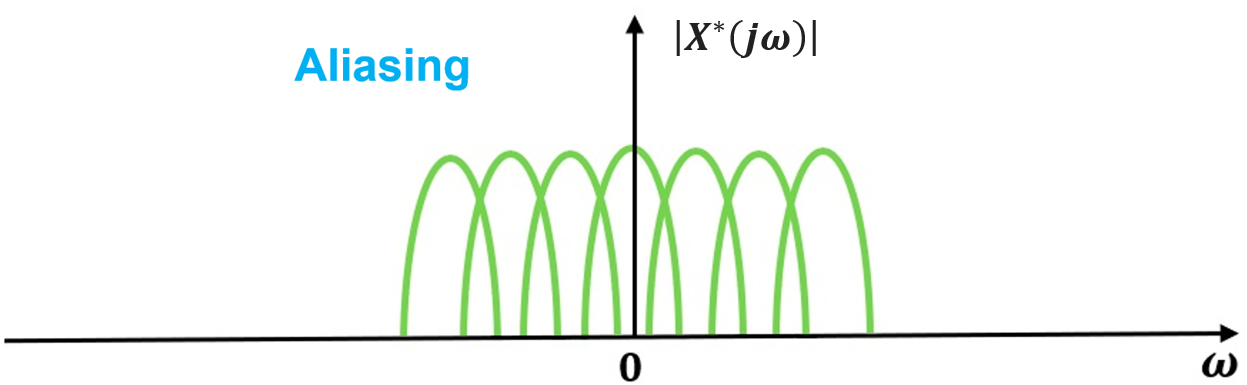

Figure 8. Frequncy spectrum of sampled signal with an incorrect (too slow) selection of sampling frequency

**Exercise**: Consider an y system G. Select a sampling frequency smaller than Shanon frequency, compute the coresponding sampling period. Sample the output signal with the sampling period you compute. Plot the spectrum of the sampled signal. You can use the code in section 4.2 as a start point.

### 4.4 Further observations

Up to now, this file has considered that band-limited signals are sampled, however we need to emphasise that most of the signals in real word are not band-limited as seen in Figure 9. Therefore sampling of these signals will inevitably cause interference in high frequencies.

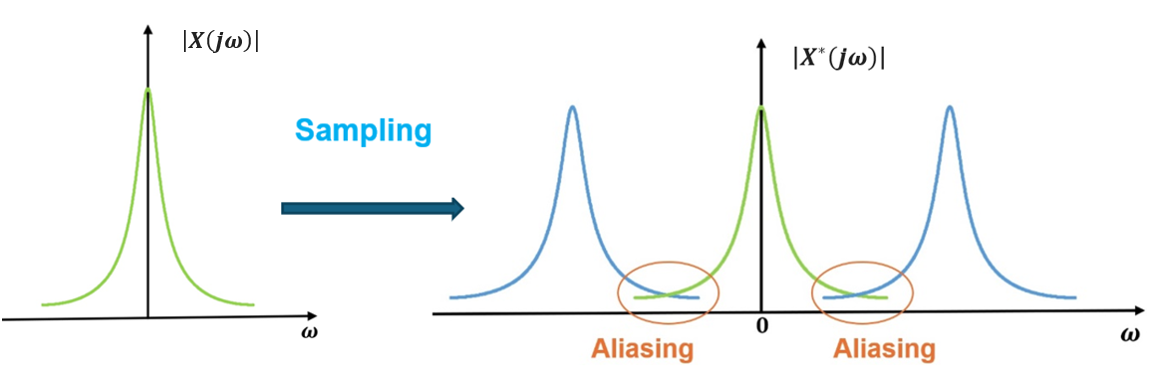

Figure 9 Sampling of non-band limited signals

Anti-aliasing filters remove the high frequency noisy components of the signal and yield a band-limited signal. Consequently with a correct selection of the sampling period, the aliasing in spectrum of the corresponding sampling signals is prevented. The anti-aliasing filter should be used before the sampling operation which yields band-limited signals ideally as in seen in Figure 10.

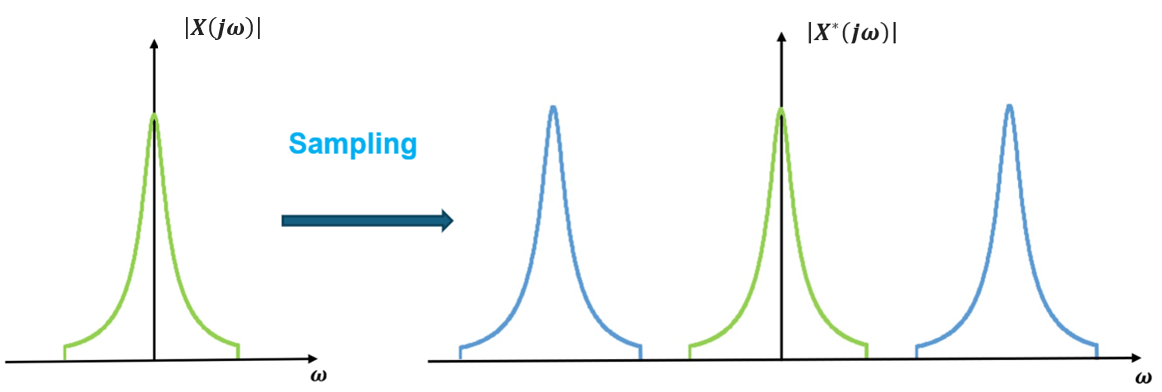

Figure 10 After-anti aliasing filter sampling of the signal

**Note**:  As seen in the examples and exercises, not all input signals and consequently the correesponding output signals are an L2 signal (i.e., energy signal),  meaning their Fourier Transforms are not defined (i.e., not finite). However, considering that systems operate with signals of finite duration, whether short or long, the Fourier Transforms have been obtained by considering the truncated versions of these signals, which belong to L2e.

## 5 The ADC virtual laboratory

A virtual laboratory ***Analog_to_Digital_Converter_Application_control101.mlapp ***has been developed to help users explore the concepts in a friendly environment by simple changes to settings through sliders. The interface as seen in Figure 11 below is intuitive to use. The max and min sliders set limits on allowable values which reflects what may happen reality.

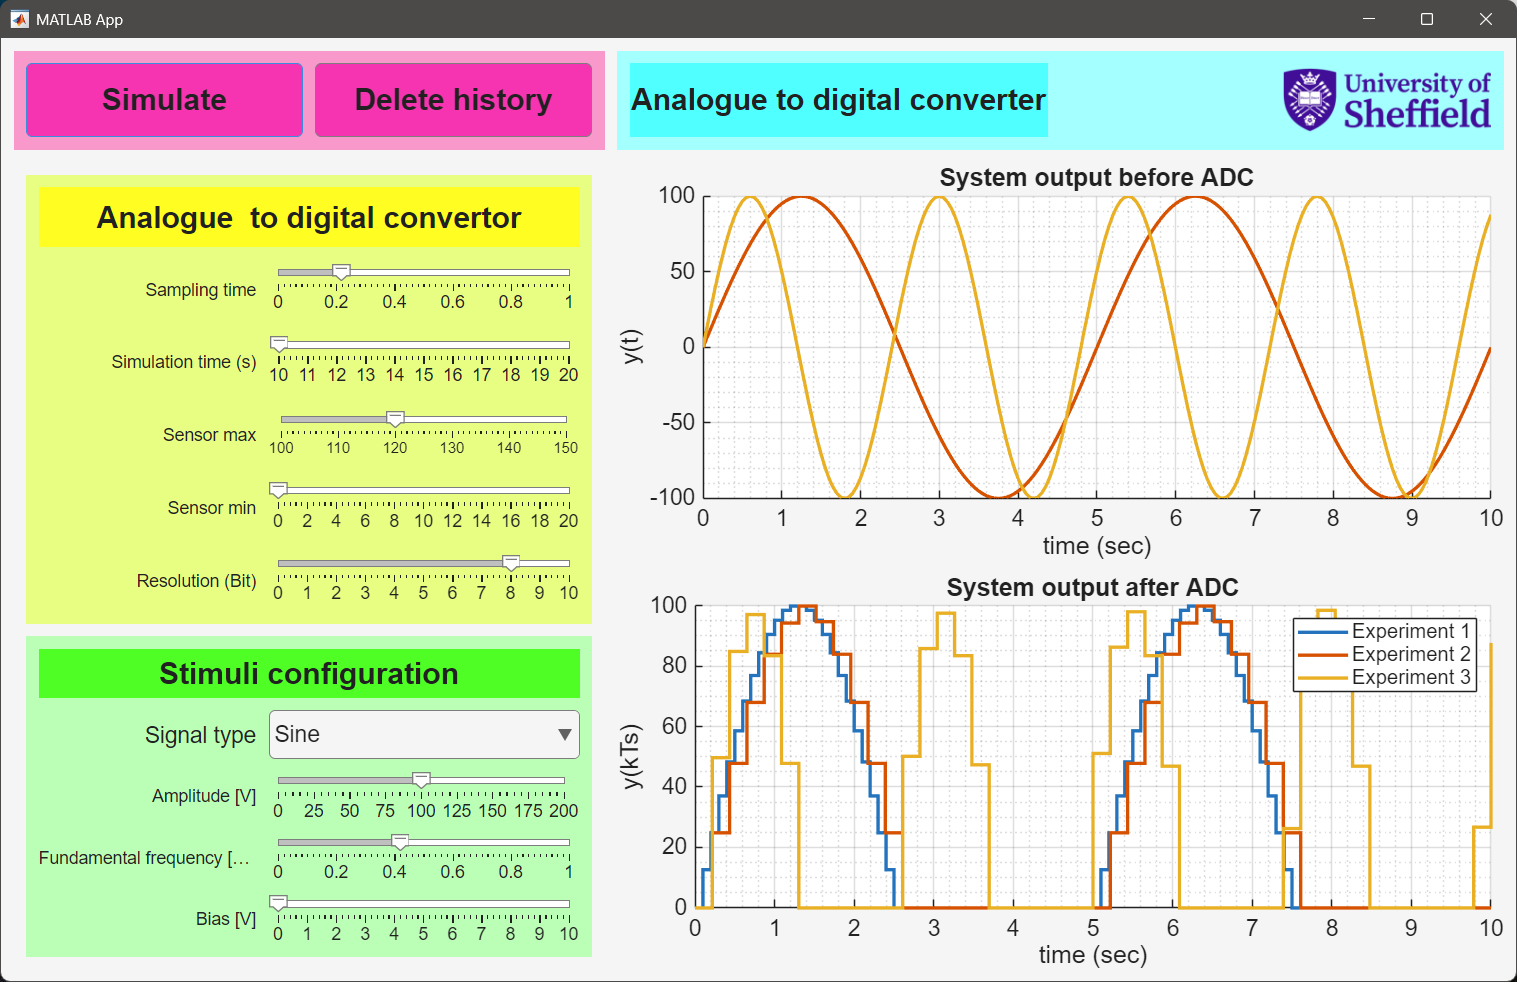

Figure 11: Interface fo the app ***Analog_to_Digital_Converter_Application_control101.mlapp***

## References

[1] Wittenmark, Björn, Karl-Erik Årzén, and Karl Johan Åström. "Computer control: An overview." *IFAC Professional Brief* , 2002.

[2] Goren-Sumer, Leyla, Bilgisayar Kontrollü Sistemler ders slaytları (Lecture slides of Computer-Controlled Systems), 2021.

[3] Ogata, Katsuhiko. *Discrete-time control systems*. Prentice-Hall, Inc., 1995.

Note: Some assistance from ChatGPT was used in developing the MATLAB codes of examples.